# ***Εργασία 2024***

### *Χρήστος Λεβαντής, 321-2020110*

% Γενικά, τα script έχουνε σχόλια, απλά είναι στα ελληνικά και άμα έχετε
% παλία έκδοση MATLAB μάλλον δεν θα τα διαβάσει (δεν το σκέφτηκα από την άρχη)
% --
% Κάλο είναι να τρέχετε τις συνάρτήσεις μια μια, και όχι όλες μαζί γιατι
% εξαρτώνται η μια από την άλλη.

## Ερώτημα 1

% Κάλουμε συνάρτηση
messageSource_1();

Η εντροπία της πηγής είναι: 0.38 bits


## Ερώτημα 2

% Κάλουμε συνάρτηση
local_randomness_2();

Η εντροπία της τυχαιότητας είναι: 6.00 bits
Η υπό συνθήκη εντροπία είναι: 3.00 bits
Η αμοιβαία πληροφορία είναι: 3.00 bits


## Ερώτημα 3

% Κάλουμε συνάρτηση
apply_crc_3();

## Ερώτημα 4

% Κάλουμε συνάρτηση
apply_hamming_coding_4();
% Βοήθεια για κατανόηση Hamming coding:
% https://www.youtube.com/watch?v=WdmGSWrcMvM
% --
% Στην εκφώνηση ζητά να γίνει κωδικοποιήση σε 24 bits
% έγω στο προηγούμενο ερώτημα έβγαλα τα μηνύματα σε 32 bits.
% Προσπάθησα να χρησιμοποιήσω την comm.HammingEncoder αλλά δεν
% υποστηρίζεται σε νέες εκδόσεις.
% --
% Κάθε 4-bit θα κωδικοποιηθεί σε 7-bit κωδικολέξη.
% Οπότε έχουμε μηνύματα με μέγεθος 32-bit άρα 32/4 = 8bit
% Τελικά θα έχουμε 8 * 7 = 56 bit μέγεθος κάθε μηνύματος.
% Συνολικά bits 56 * 100000 = 5600000 bits
% --
% Οι πιθανές λέξεις: Αφού χρησιμοποιώ Hamming(7, 4) που αντιστοιχίζει 
% μηνύματα 4-bit σε κωδικοποιημένες λέξεις 7-bit. Υπάρχουν λοιπόν 2^4 = 16
% πιθανές λέξεις καθέ μια να αντιστοιχίζεται σε 7-bit κωδικολέξη. 
% Καταλαβαίνουμε ότι 2^7 = 128 πιθανές κωδικολέξεις.
% Επίσης δωσμένου ότι αρχικά έχουμε 32-bit μηνύματα 32/4 = 8 segments
% ο συνολικός αριθμός των 56 λέξεων είναι 2^4*8 = 2^32.
% --

#### Για υπολογισμό των πιθανοτήτων εμφάνισης έχουμε την συνάρτηση (Ερώτημα 4)

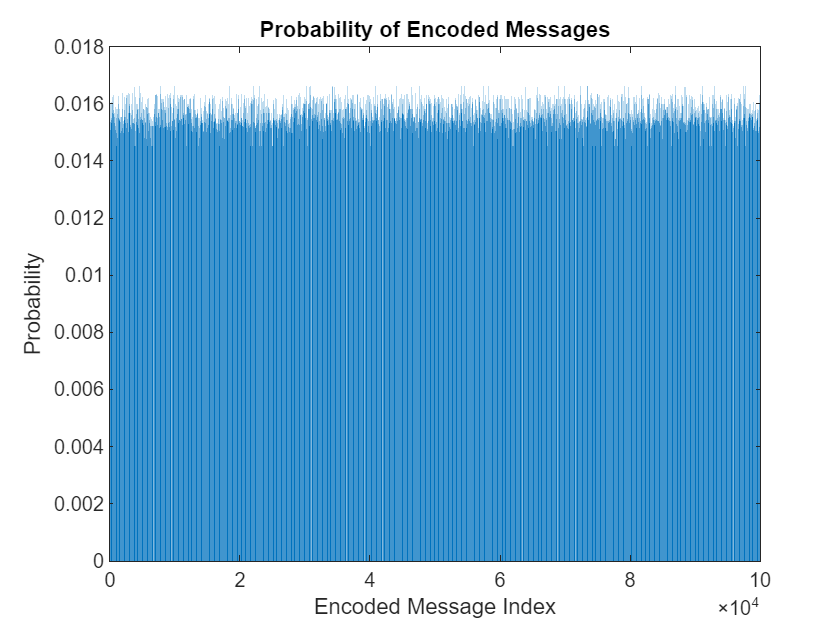

calculate_probabilities_4();

% Μετά την εκτέλεση αυτής θα δούμε ότι όλες οι πιθανότητες είναι κοντά
% στο 0,016 κάτι το οποίο δείχνει ομοιόμορφη κατανομή.